# Teoría 7: Interpolación

## Polinomio interpolante

$f(x)=P_n(x)$ si y solo sí $y=a_{n-1}x^{n-1}+\cdots+a_{1}x+a_0$

Hay $n$ incognitas (coeficientes)

- Se necesitan $n$ datos $(x_i,y_i)$: $(x_0,y_0),(x_1,y_1),\dots,(x_{n-1},y_{n-1})$

Evaluando se llega al **sistema** (lineal) **determinado** 

                                        
$$M a = y$$


% Datos de ejemplo
x = [0 3 4 7]';
y = [5 2 6 9]';

M = vander(x)

M =      0     0     0     1
    27     9     3     1
    64    16     4     1
   343    49     7     1


a = M\y % coeficientes del polinomio

a =    -0.2857
    3.2500
   -8.1786
    5.0000


Veamos el polinomio

syms t
p_new = sum(a' .* [t^3 t^2 t 1])

$$p\_new = -\frac{2\,t^{3}}{7}+\frac{13\,t^{2}}{4}-\frac{229\,t}{28}+5$$

format rational
p_poly = polyfit(x,y,length(x)-1) % coeficientes

p_poly =       -2/7           13/4         -229/28           5       


format short

## Polinomio interpolante de Newton

% Datos de ejemplo
x = [0 3 4 7]';
y = [5 2 6 9]';

% Tabla de diferencias divididas
M = tabladif(x, y)

M =          0    5.0000   -1.0000    1.2500   -0.2857
    3.0000    2.0000    4.0000   -0.7500         0
    4.0000    6.0000    1.0000         0         0
    7.0000    9.0000         0         0         0



$$P_n(x)=y[x_0]+y[x_0,x_1](x-x_0)+y[x_0,x_1,x_2](x-x_0)(x-x_1)+y[x_0,x_1,x_2,x_3](x-x_0)(x-x_1)(x-x_2)$$


% Polinomio de Newton
p_newton = polynewton(x, y)

p_newton =    -0.2857    3.2500   -8.1786    5.0000


## Polinomio interpolante de Lagrange

% Datos de ejemplo
x = [0 3 4 7]';
y = [5 2 6 9]';

% Polinomio de Lagrange
p_lagrange = lagrange(x, y)

p_lagrange =    -0.2857    3.2500   -8.1786    5.0000


## Comparación

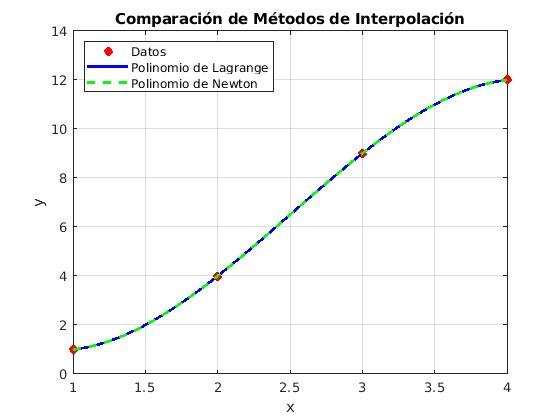

% Datos de ejemplo
x = [1, 2, 3, 4];
y = [1, 4, 9, 12];

% Polinomio de Newton
p_newton = polynewton(x, y);

% Polinomio de Lagrange
p_lagrange = lagrange(x, y);

% Para evaluar
xq = linspace(1, 4, 100);

% Evaluar los polinomios en un conjunto de puntos
yq_lagrange = polyval(p_lagrange, xq);
yq_newton = polyval(p_newton, xq);

% Graficar los datos y los polinomios de interpolación
figure;
plot(x, y, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(xq, yq_lagrange, 'b-', 'LineWidth', 2);
plot(xq, yq_newton, 'g--', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Comparación de Métodos de Interpolación');
legend('Datos', 'Polinomio de Lagrange', 'Polinomio de Newton',"Location","northwest");
grid on;
hold off;

function p = lagrange(x, y)
    %   p = LAGRANGE(x, y) devuelve los coeficientes del polinomio de interpolación
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       p - Vector de coeficientes del polinomio de interpolación de Lagrange.

    n = length(x);      % Número de puntos
    p = zeros(1, n);    % Inicializar el polinomio resultante

    % Construir el polinomio de Lagrange
    for k = 1:n
        num = poly(x([1:k-1, k+1:n])); % Numerador del término de Lagrange
        den = polyval(num, x(k));      % Denominador del término de Lagrange
        L = num / den;                 % Término de Lagrange
        p = p + y(k) * L;              % Sumar el término de Lagrange al polinomio
    end
end

function M = tabladif(x, y)
    %   M = TABLADIF(x, y) devuelve la tabla de diferencias divididas de Newton
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       M - Matriz donde la primera columna es x y las siguientes columnas
    %           contienen las diferencias divididas.

    n = length(x);      % Número de puntos
    M = zeros(n);       % Inicializar la matriz M
    M(1:n, 1) = y;      % Primera columna de M es y

    % Calcular las diferencias divididas
    for k = 1:n-1
        dx = x(k+1:n) - x(1:n-k); % Diferencias de x
        dy = diff(y) ./ dx;       % Diferencias divididas
        M(1:n-k, k+1) = dy;       % Llenar la columna k+1 de M
        y = dy;                   % Actualizar y para el siguiente paso
    end

    M = [x(:) M]; % Añadir la columna x al principio de la matriz M
end

function p = polynewton(x, y)
    %   p = POLYNEWTON(x, y) devuelve los coeficientes del polinomio de interpolación
    %
    %   Entrada:
    %       x - Vector de valores de la variable independiente.
    %       y - Vector de valores de la variable dependiente.
    %
    %   Salida:
    %       p - Vector de coeficientes del polinomio de interpolación de Newton.

    M = tabladif(x, y); % Obtener la tabla de diferencias divididas
    n = length(x);      % Número de puntos
    b = M(1, 2:end);    % Coeficientes del polinomio de Newton
    p = b(1);           % Inicializar el polinomio con el primer coeficiente

    % Construir el polinomio de Newton
    for k = 2:n
        % Actualizar el polinomio con el siguiente término
        p = [0 p] + b(k) * poly(x(1:k-1)); 
    end
end